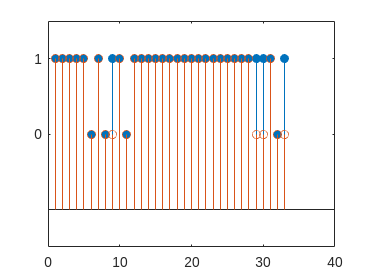

% Machine learning testing
% You need to import data before you can run code!
data = parkinsons;
positive = 1;
negative = 0;

% classes
c = data(:, "status");

% Test set
t = data(1:6:end, :);
t = t(:, 2:end);
t(:, "status") = [];
t = table2array(t);
tc = table2array(c(1:6:end, :));

% Training set
tr = data(:,2:end);
tr(1:6:end, :) = [];
tr(:, "status") = [];
tr = table2array(tr);
trc = c;
trc(1:6:end, :) = [];
trc = table2array(trc);

% Support vector machines
svm = fitcsvm(tr, categorical(trc));

psvm = predict(svm,t);

stem(psvm, 'filled');
hold on
stem(categorical(tc));
hold off

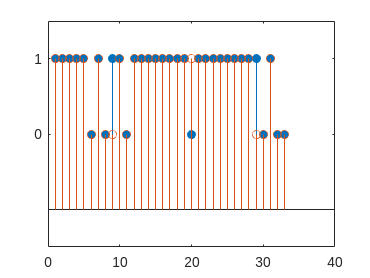


% Decision tree
dt = fitctree(tr, categorical(trc));
pdt = predict(dt, t);

stem(pdt, 'filled');
hold on
stem(categorical(tc));
hold off


accuracy = tc==pdt;

Error using  ==  (line 30)
Comparison is not defined between double and categorical arrays.